clear; clc; close all;

filename = 'pnas.2400304121.sd01.xlsx'; % Held et al. (2024) Data from Excel

raw = readcell(filename, 'Sheet', 'Tab 1 Growth rates');

headerRow = [];
for r = 1:min(20, size(raw,1))
    if ischar(raw{r,1}) && strcmpi(strtrim(raw{r,1}), 'Well')
        headerRow = r;
        break;
    end
end

dataStart = headerRow + 1;
nRows = size(raw, 1) - dataStart + 1;

col_G_conc = 2;    % Glucose (mM)
col_A_conc = 3;    % Ammonium (mM)
col_mu1 = 4;    % Growth rate rep 1
col_mu2 = 10;   % Growth rate rep 2
col_mu3 = 16;   % Growth rate rep 3

M_G_exp = zeros(nRows, 1);
M_A_exp = zeros(nRows, 1);
mu_all  = nan(nRows, 3);

for i = 1:nRows
    row = dataStart + i - 1;
    M_G_exp(i) = getNumeric(raw{row, col_G_conc});
    M_A_exp(i) = getNumeric(raw{row, col_A_conc});
    mu_all(i,1) = getNumeric(raw{row, col_mu1});
    mu_all(i,2) = getNumeric(raw{row, col_mu2});
    mu_all(i,3) = getNumeric(raw{row, col_mu3});
end


valid = all(~isnan(mu_all), 2) & M_G_exp > 0 & M_A_exp > 0;
M_G_exp = M_G_exp(valid);
M_A_exp = M_A_exp(valid);
mu_exp_avg  = mean(mu_all(valid, :), 2);

fprintf('Loaded %d valid experimental points.\n', numel(mu_exp_avg));

Loaded 54 valid experimental points.



    function g = growth_function(params, M_G, M_A, model_type)
        c0  = params(1);
        coeff_G = params(2);
        coeff_A = params(3);
        
        switch model_type
            case 'additive'
                g = c0 * (coeff_G .* M_G + coeff_A .* M_A);
            case 'monod'
                K_G = params(4);
                K_A = params(5);
                g = c0 * ( (coeff_G .* M_G) ./ (1 + M_G./K_G) + ...
                           (coeff_A .* M_A) ./ (1 + M_A./K_A) );
            case 'liebig'
                g = c0 * min(coeff_G .* M_G, coeff_A .* M_A);
        end
    end

model_types = {'additive', 'monod', 'liebig'};
results = struct();

for i = 1:3
    mt = model_types{i};
    
    if strcmp(mt, 'monod')
        log_p0 = log([1, 10, 10, 0.5, 0.5]); 
    else
        log_p0 = log([1, 10, 10]); 
    end
    
    obj_fun = @(lp) sum((mu_exp_avg - growth_function(exp(lp), M_G_exp, M_A_exp, mt)).^2);
    
    options = optimset('Display', 'off', 'MaxFunEvals', 1e5, 'TolFun', 1e-10);
    [log_p_fit, sse] = fminsearch(obj_fun, log_p0, options);
    
    results(i).type = mt;
    results(i).params = exp(log_p_fit);
    results(i).sse = sse;
    results(i).mu_pred = growth_function(results(i).params, M_G_exp, M_A_exp, mt);
    

    ss_tot = sum((mu_exp_avg - mean(mu_exp_avg)).^2);
    results(i).r2 = 1 - (sse / ss_tot);
end


fprintf('\n MODEL COMPARISON SUMMARY \n');


 MODEL COMPARISON SUMMARY 


fprintf('%-12s %-10s %-12s\n', 'Growth', 'R^2', 'SSE');

Growth       R^2        SSE         


for i = 1:3
    fprintf('%-12s %-10.4f %-12.6f\n', results(i).type, results(i).r2, results(i).sse);
end

additive     -5.7027    4.770109    
monod        0.7321     0.190676    
liebig       -9.0367    7.142803    


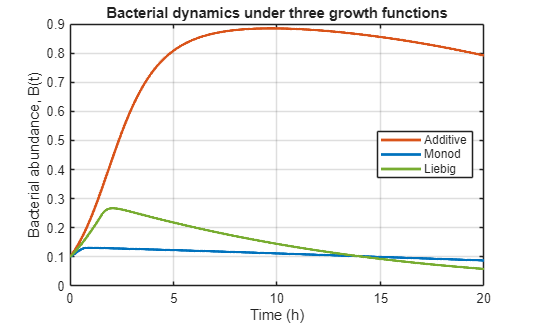


    function dydt = ode_model(~, y, p_growth, p_eco, model_type) % Coupled ODEs (Jansma et al.(2026))
        B   = max(y(1), 0);
        M_G = max(y(2), 0);
        M_A = max(y(3), 0);
        
   
        g = growth_function(p_growth, M_G, M_A, model_type);
        
        dB = B * (g - p_eco.d) * (p_eco.k - B);  % Eqn 1: Bacterial Dynamics
        
        dM_G = p_eco.s_G - M_G * (p_growth(2) * B); % Eqn 2: Metabolite Dynamics (supply = 0 for closed batch)
        dM_A = p_eco.s_A - M_A * (p_growth(3) * B); 
        
        dydt = [dB; dM_G; dM_A];
    end


p_eco.d   = 0.1;   % death rate d_j
p_eco.k   = 1.0;   % carrying capacity k
p_eco.s_G = 0.0;   % batch
p_eco.s_A = 0.0; 

B0   = 0.1;        % Initial bacteria
M_G0 = 2.0;        % Initial glucose (mM)
M_A0 = 1.0;        % Initial ammonium (mM)
y0   = [B0; M_G0; M_A0];
tspan = [0 20];


ode_opts = odeset('RelTol', 1e-8, 'AbsTol', 1e-10, 'MaxStep', 0.01);

t_sol = cell(3,1); B_sol = cell(3,1); MG_sol = cell(3,1); MA_sol = cell(3,1);

for i = 1:3
    p_growth = results(i).params;
    mt = results(i).type;
    
    odefun = @(t, y) ode_model(t, y, p_growth, p_eco, mt);
    [t, y] = ode15s(odefun, tspan, y0, ode_opts);
    
    t_sol{i}  = t;
    B_sol{i}  = y(:,1);
    MG_sol{i} = y(:,2);
    MA_sol{i} = y(:,3);
end


colors = [0.8500 0.3250 0.0980; 
          0.0000 0.4470 0.7410;  
          0.4660 0.6740 0.1880];
     
labels = {'Additive', 'Monod', 'Liebig'};
      
figure('Name', 'Bacterial Dynamics');
hold on; box on; grid on;
for i = 1:3
    plot(t_sol{i}, B_sol{i}, 'LineWidth', 2, 'Color', colors(i,:));
end
xlabel('Time (h)'); ylabel('Bacterial abundance, B(t)');
title('Bacterial dynamics under three growth functions');
legend(labels, 'Location', 'east');
xlim([0 20]);

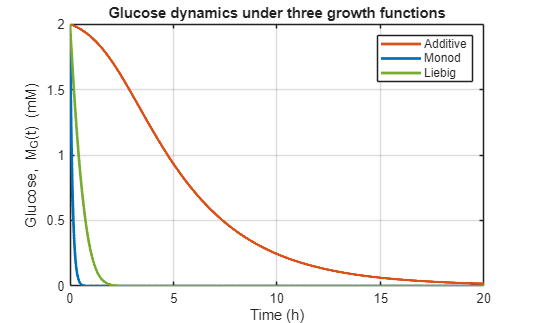


figure('Name', 'Glucose Dynamics');
hold on; box on; grid on;
for i = 1:3
    plot(t_sol{i}, MG_sol{i}, 'LineWidth', 2, 'Color', colors(i,:));
end
xlabel('Time (h)'); ylabel('Glucose, M_G(t) (mM)');
title('Glucose dynamics under three growth functions');
legend(labels, 'Location', 'northeast');
xlim([0 20]);

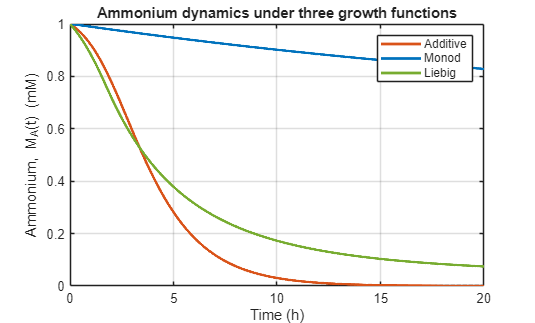


figure('Name', 'Ammonium Dynamics');
hold on; box on; grid on; 
for i = 1:3
    plot(t_sol{i}, MA_sol{i}, 'LineWidth', 2, 'Color', colors(i,:));
end
xlabel('Time (h)'); ylabel('Ammonium, M_A(t) (mM)');
title('Ammonium dynamics under three growth functions');
legend(labels, 'Location', 'northeast');
xlim([0 20]);

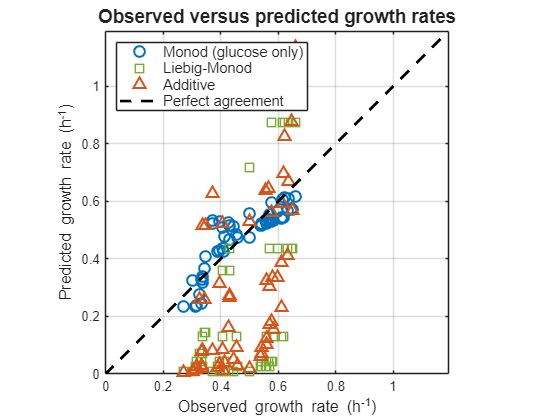


figure('Name', 'Observed vs Predicted', 'Position', [150 150 700 550]);
hold on; grid on; box on;

markers = {'^', 'o', 's'}; 

order = [2, 3, 1]; 
scatter_labels = {'Monod (glucose only)', 'Liebig-Monod', 'Additive'};
scatter_colors = [colors(2,:); colors(3,:); colors(1,:)]; 
scatter_markers = {markers{2}, markers{3}, markers{1}};

for k = 1:3
    i = order(k);
    plot(mu_exp_avg, results(i).mu_pred, scatter_markers{k}, ...
        'MarkerSize', 8, ...
        'MarkerEdgeColor', scatter_colors(k,:), ...
        'MarkerFaceColor', 'none', ...
        'LineWidth', 1.5, ...
        'DisplayName', scatter_labels{k});
end

lims = [0, max([mu_exp_avg; results(1).mu_pred; results(2).mu_pred; results(3).mu_pred]) * 1.05];

plot(lims, lims, 'k--', 'LineWidth', 2, 'DisplayName', 'Perfect agreement');

xlabel('Observed growth rate (h^{-1})', 'FontSize', 12);
ylabel('Predicted growth rate (h^{-1})', 'FontSize', 12);
title('Observed versus predicted growth rates', 'FontSize', 14, 'FontWeight', 'bold');
legend('Location', 'northwest', 'FontSize', 11);
axis equal;
xlim(lims);
ylim(lims);
hold off;


function val = getNumeric(x)
    if isnumeric(x)
        val = double(x);
    elseif ischar(x) || isstring(x)
        val = str2double(x);
        if isnan(val), val = NaN; end
    else
        val = NaN;
    end
end